dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];

imgDir = fullfile(pwd, dataFolder, '/train', 'images');
imds = imageDatastore(imgDir, 'readfcn',@(filename) custominputreader(imread(filename)));

floodLabelSmoothThreshold = 0.3;
sigma = 2;
labelDir = fullfile(pwd, dataFolder, '/train', 'labels');
filllabeler =  @(image) customlabelreader(image, floodLabelSmoothThreshold, sigma);
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs,'readfcn',@(filename) filllabeler(imread(filename)));
a = combine(imds, pxds)

a =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 matlab.io.datastore.PixelLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


a.read()

ans = 1×2 cell array
    {1016×1234×2 uint8}    {1016×1234 categorical}


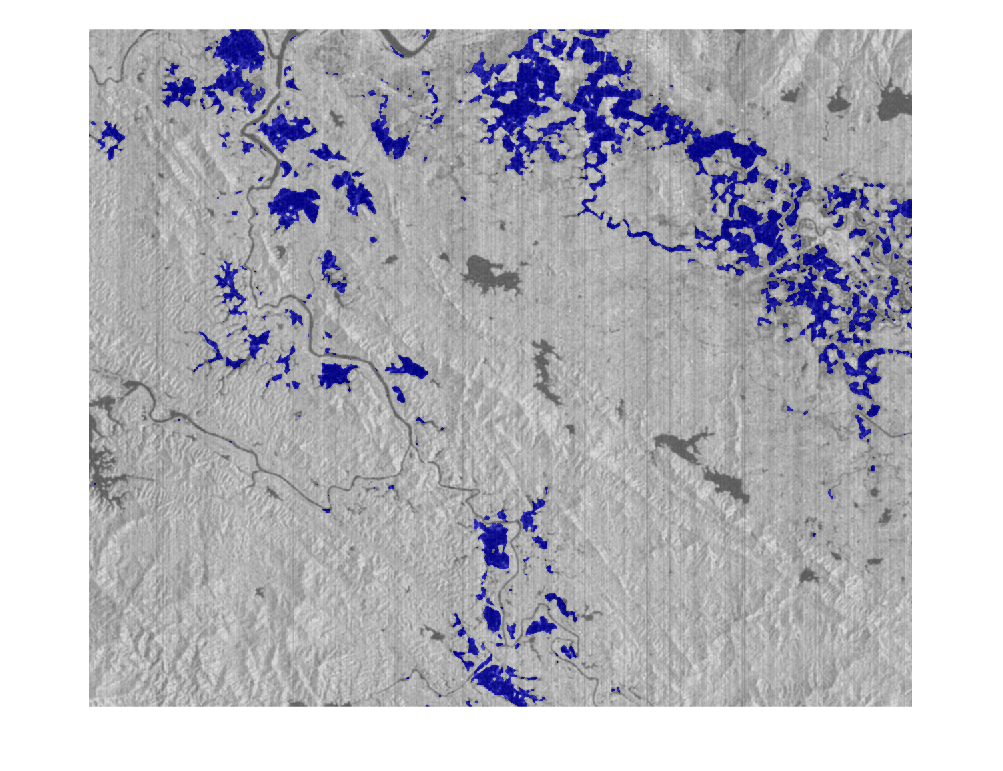

i = imds.preview;
c = pxds.preview;
i1 = normalize(double(i), 'range', [0 1]);
i1 = i1(:,:,1);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    3.3999e+07      3.5297e+07   
    {'flood'   }    1.2977e+06      3.5297e+07   


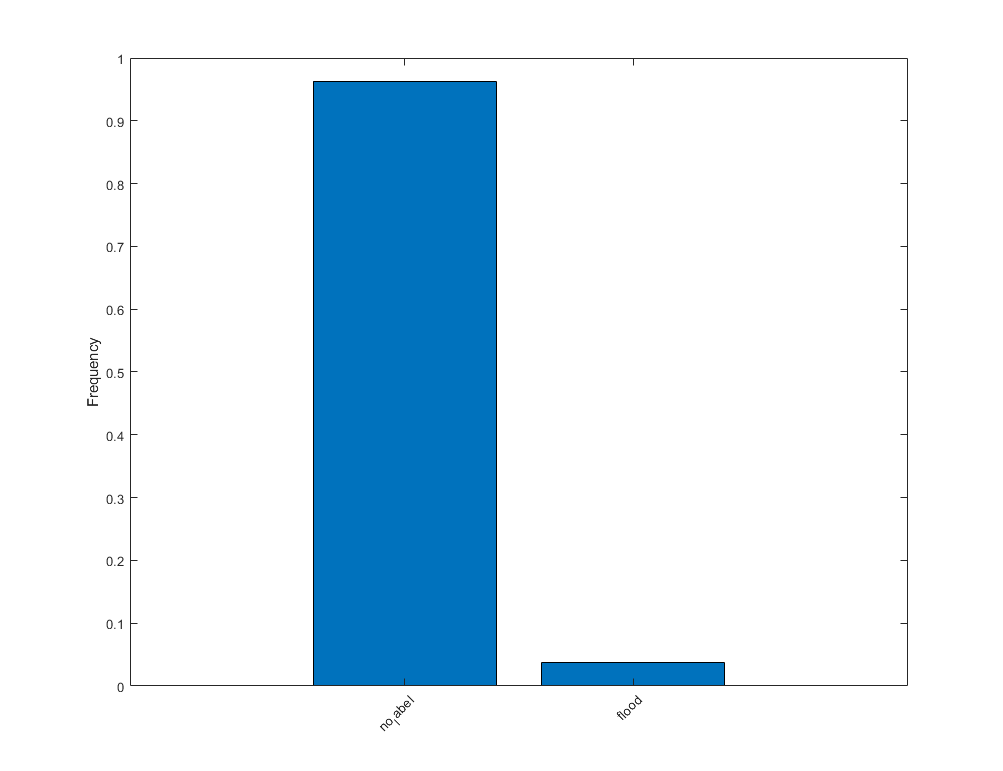

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes))
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.5191
   13.6003


inputTileSize = [128, 128, 2];
patchesPerImage = 50;
biasThreshold = 0.5;
timeToLoop = 10000;

augmenter = imageDataAugmenter("RandRotation",[-90, 90], ...
    "RandYTranslation", [-10 10], ...
    'RandXTranslation', [-10 10], ...
    "RandXReflection", true);
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), biasThreshold, timeToLoop, "PatchesPerImage", patchesPerImage, 'DataAugmentation', augmenter);
inputBatch = preview(dsTrain);
disp(inputBatch)

       InputImage        ResponsePixelLabelImage
    _________________    _______________________

    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 
    {128×128×2 uint8}     {128×128 categorical} 



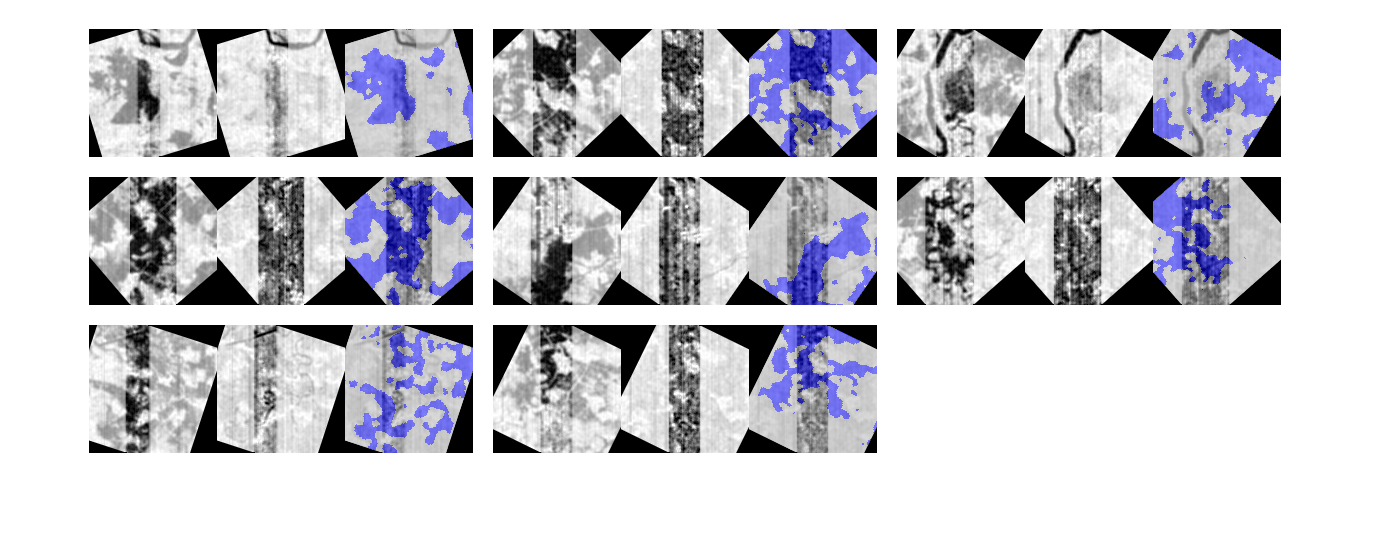

showImageWithLabel(inputBatch)

valImgDir = fullfile(pwd, dataFolder, '/validate', 'images');
valImds = imageDatastore(valImgDir,'readfcn',@(filename) custominputreader(imread(filename)));
valLabelDir = fullfile(pwd, dataFolder, '/validate', 'labels');
valPxds = pixelLabelDatastore(valLabelDir, classes, pixelLabelIDs, 'readfcn', @(filename) filllabeler(imread(filename)));
dsValidate = imbalanceRandomPatchExtractionDatastore(valImds, valPxds, inputTileSize(1:2), biasThreshold, timeToLoop, ...
    "PatchesPerImage", patchesPerImage, ...
    'DataAugmentation', augmenter);
a = combine(valImds, valPxds)

a =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 matlab.io.datastore.PixelLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


a.read()

ans = 1×2 cell array
    {1264×2676×2 uint8}    {1264×2676 categorical}


pxLayer = pixelClassificationLayer('Name','Pixel-Classification-Layer');%,'Classes',tbl.Name);%,'ClassWeights',classWeights);
lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
% lgraph = unetLayers(inputTileSize, numel(classes), "EncoderDepth", 4);
% lgraph = replaceLayer(lgraph, 'Segmentation-Layer', pxLayer);
disp(lgraph.Layers)

  58×1 Layer array with layers:

     1   'ImageInputLayer'                        Image Input                  128×128×2 images with 'zerocenter' normalization
     2   'Encoder-Section-1-Conv-1'               Convolution                  64 2×2×2 convolutions with stride [1  1] and padding 'same'
     3   'Encoder-Section-1-ReLU-1'               ReLU                         ReLU
     4   'Encoder-Section-1-Conv-2'               Convolution                  64 2×2×64 convolutions with stride [1  1] and padding 'same'
     5   'Encoder-Section-1-ReLU-2'               ReLU                         ReLU
     6   'Encoder-Section-1-MaxPool'              Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'Encoder-Section-2-Conv-1'               Convolution                  128 2×2×64 convolutions with stride [1  1] and padding 'same'
     8   'Encoder-Section-2-ReLU-1'

initialLearningRate = 0.05;
maxEpochs = 100;
minibatchSize = 8;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor', 0.1,...
    'LearnRateDropPeriod', 2,...
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    'ValidationData', dsValidate,...
    'ValidationFrequency', 100,...
    'GradientThreshold',0.5,...
    "ExecutionEnvironment","gpu");
%     "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

% doTraining = true;
% if doTraining
%     modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
%     [net,info] = trainNetwork(dsTrain,lgraph,options);
%     %     save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
% end